# **Introductory script illustrating how to compute cone mosaic excitation response from an ISETBio scene representing a stimulus rendered on a particular display**

#### **See also**: 

- `t_sceneForStimulusOnDisplay.mlx`  (more info on scene generation)

*Copyright: Nicolas P. Cottaris,  ISETBio Team,, 2018*

# OUTLINE

 **   Step 1.** Create a presentation display and a Gabor stimulus realized on that display

 **   Step 2.** Compute the optical image using wavefront-aberration based optics

   ** Step 3.** Create a cone mosaic object and compute its isomerization response to the optical image for a 20 msec presentation

# **Step 1.** Create a presentation display and a Gabor stimulus realized on that display

We employ an existing display specification, here an Apple LCD display and some typical params for a Gabor stimulus.

%% Create presentation display
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.57);

%% parameter struct for a Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 10, ... % 10 cycles/deg
    'orientationDegs', 0, ...               % 45 degrees
    'phaseDegs', 90, ...                    % spatial phase degrees
    'sizeDegs', 0.4, ...                    % 0.x4 x 0.4 size
    'sigmaDegs', 0.2/3, ...                 % sigma of Gaussian envelope
    'contrast', 0.6,...                     % 0.6 Michelson contrast
    'meanLuminanceCdPerM2', 40 ...          % 40 cd/m2 mean luminance
    );

% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(stimParams,...
    'presentationDisplay', presentationDisplay);

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene);

# **Step 2.** Compute the optical image using wavefront-aberration based optics

We employ an existing display specification, here an Apple LCD display and some typical params for a Gabor stimulus.

%% Generate wavefront-aberration derived human optics
opticalImage = oiCreate('wvf human');

%% Compute the retinal image
opticalImage = oiCompute(opticalImage, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(opticalImage);

# **Step 3.** Create a cone mosaic object and compute its isomerization response to the optical image for a 20 msec presentation

We generate a hex, eccentricity varying cone mosaic, set its integration time to 20 msec, and compute its excitation response.

%% Generate a hexagonal cone mosaic with ecc-based cone quantal efficiency
coneMosaic = coneMosaicHex(7, ...             % hex lattice sampling factor
   'fovDegs', stimParams.sizeDegs, ...        % match mosaic width to stimulus size
   'eccBasedConeDensity', true, ...           % cone density varies with eccentricity
   'eccBasedConeQuantalEfficiency', true, ... % cone quantal efficiency varies with eccentricity
   'integrationTime', 20/1000, ...            % 50 msec integration time
   'maxGridAdjustmentIterations', 50);        % terminate iterative lattice adjustment after 50 iterations

%% Compute mosaic responses to a number of stimulus presentations and assume zero eye movements
nTrialsNum = 50;   % generate 50 response instances
eyeMovementPath = zeros(nTrialsNum, 1, 2);
coneExcitations = coneMosaic.compute(opticalImage, ...
    'emPath', eyeMovementPath);

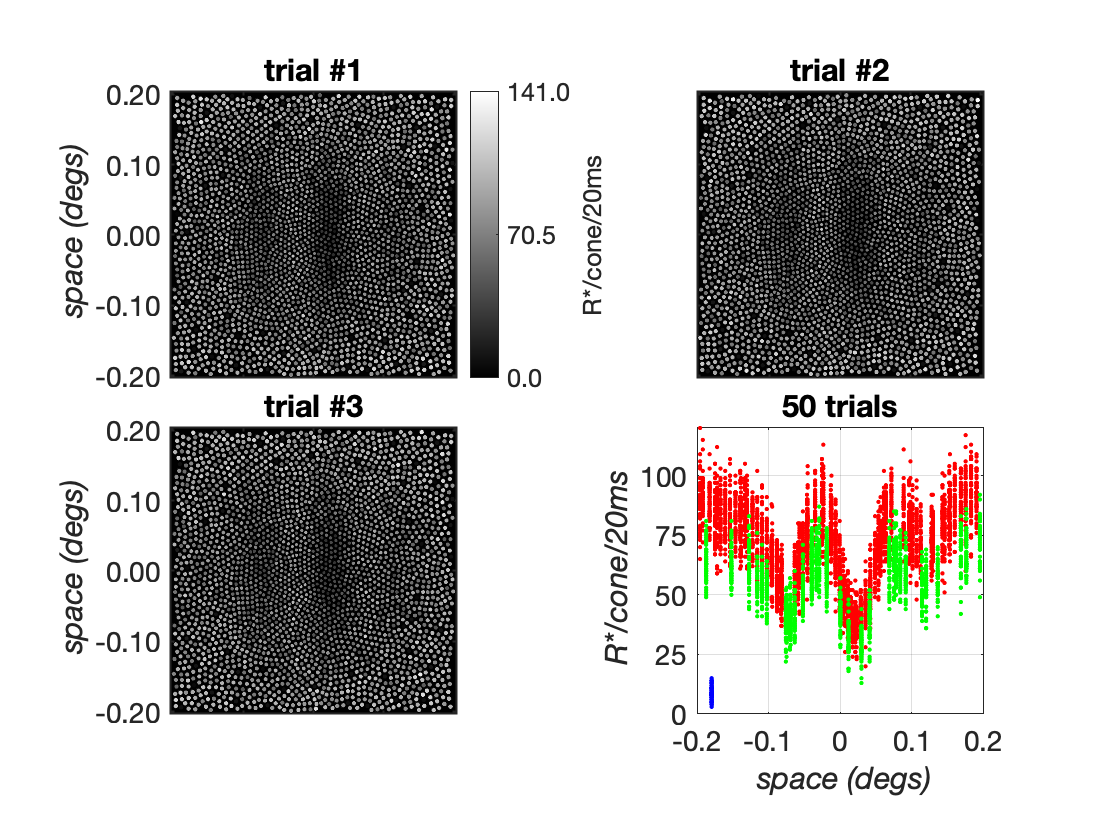

%% Visualize mosaic responses
visualizeConeMosaicResponses(coneMosaic, coneExcitations);